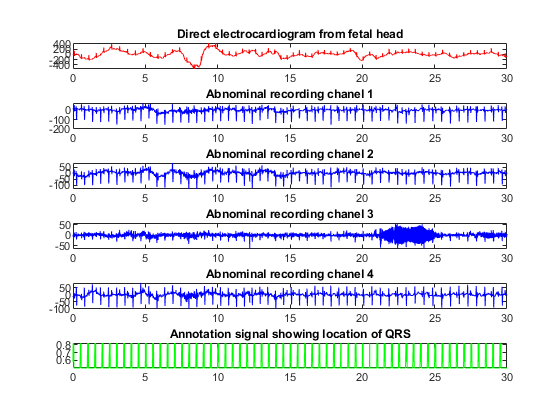

clc
load("Abdominal_rec.mat")
%[hdr, record] = edfread("/MATLAB Drive/Biomedical Project/Full data/r01.edf ");
%the ECG signals are Loaded and storred in record1, record2,record3,.......record6,
%their headers are in Hhdr1, hdr2, hdr3 etc
signal = record5(:,1:30000);%%% change his to test for differnt signal
Fs = 1000;
%Visualise signal in time domain
time = 0:1/Fs:30-1/Fs;
%Preprocessing 

figure

for i = 1:6
    subplot(6,1,i)
    
    if i == 1
        
        plot(time(1:30000),signal(i,1:30000),'r')
        title("Direct electrocardiogram from fetal head")
    elseif i == 6
        
        plot(time(1:30000),signal(i,1:30000),'g')
        title("Annotation signal showing location of QRS")
    else
        tittlt = ['Abnominal recording chanel ',num2str(i-1) ];
        
        plot(time(1:30000),signal(i,1:30000),'b')
        title(tittlt)
    end
    
    
end

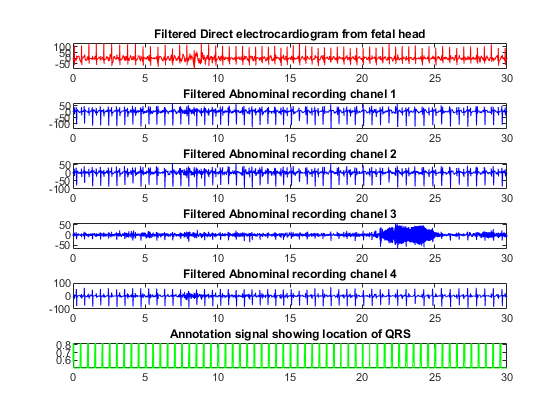


%BandPass Zero Phase filtering of signal

FiltECG = BandPassZeroPhasefilt(signal, 2,70,2000,1000);
figure

for i = 1:6
    subplot(6,1,i)
    
    if i == 1
        
        plot(time(1:30000),FiltECG(i,1:30000),'r')
        title("Filtered Direct electrocardiogram from fetal head")
    elseif i == 6
        
        plot(time(1:30000),FiltECG(i,1:30000),'g')
        title("Annotation signal showing location of QRS")
    else
        tittlt = ['Filtered Abnominal recording chanel ',num2str(i-1) ];
        
        plot(time(1:30000),FiltECG(i,1:30000),'b')
        title(tittlt)
    end
    
    
end

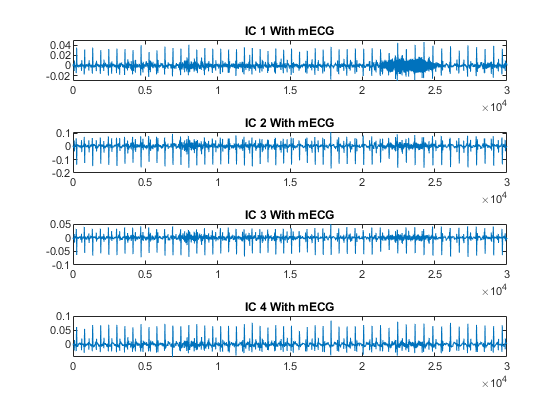


AbRec = FiltECG(2:5,:);

% ---- Independent Component Analysis ----

covsig = AbRec*AbRec';
[U,eigval] =eig(covsig);
%[UU SS VV] = svd(Covsig)
PCs = U*AbRec;
PCs = PCs'/sqrt(eigval);
mdl = rica(PCs,4);
ICs = PCs*mdl.TransformWeights;
ICs = ICs';
%visualise

 figure
for i = 1:4
    subplot(4,1,i)
    plot(ICs(i,1:30000))
    tittlt = ['IC ', num2str(i),' With mECG' ];
    title(tittlt)
    
end 

%Channel selection and Mother QRS detection
qrsM=chanelSelection(ICs',Fs);

Number of detected mother QRSs= 53


makers =  0.82*ones(1,length(qrsM));
% ---- Mother QRS cancelling
SnMECG=FecgQRSmCanc(ICs',qrsM,Fs,'signal');


 --------------------------------------------------------- 
Program:  FecgQRSmCanc,  record name: signal
Number of QRSs= 53
RR mean= 5.649583e-01,  stdev=2.379902e-02
is=1, pownds=0.900286
is=2, pownds=0.935891
is=3, pownds=0.937728
is=4, pownds=0.945970


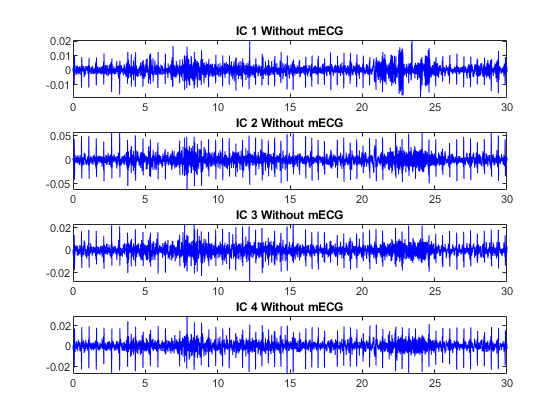


SnMECG = SnMECG';

figure
for i = 1:4
    subplot(4,1,i)
    plot(time, SnMECG(i,1:30000),'b')
    tittlt = ['IC ', num2str(i),' Without mECG' ];
    title(tittlt)     
    
end 

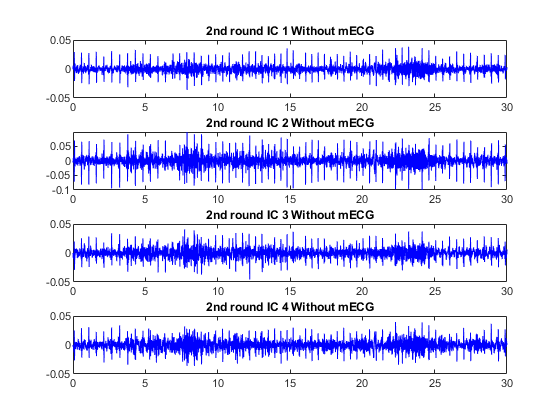

% Independent Component Analysis 
%to finaly separate the moternal signal
AbRec = SnMECG;
covsig = AbRec*AbRec';
[U,eigval] =eig(covsig);
%[UU SS VV] = svd(Covsig)
PCs = U*AbRec;
PCs = PCs'/sqrt(eigval);
mdl = rica(PCs,4);
ICs = PCs*mdl.TransformWeights;
ICs = ICs';

%visualise
figure
for i = 1:4
    subplot(4,1,i)
    plot(time, ICs(i,1:30000),'b')
    tittlt = ['2nd round IC ', num2str(i),' Without mECG' ];
    title(tittlt)
    
end 


[qrsF ch]=FecgQRSfDet(ICs',Fs,"signal",qrsM);


 --------------------------------------------------------- 
Program: FecgQRSfDet,   record name: signal
Number of annotated fetal QRSs= 1
channel=1,  meRR= 0.4710,  madRR= 0.0101,  maddRR= 0.0169, cfact= 0.0000, cFMsim= 0.0110
channel=2,  meRR= 0.4710,  madRR= 0.0070,  maddRR= 0.0089, cfact= 0.0000, cFMsim= 0.0110
channel=3,  meRR= 0.4740,  madRR= 0.0192,  maddRR= 0.0319, cfact= 0.0000, cFMsim= 0.0119
channel=4,  meRR= 0.4700,  madRR= 0.0189,  maddRR= 0.0305, cfact= 0.0000, cFMsim= 0.0119
channel=1,  chanIqf= 0.0380
channel=2,  chanIqf= 0.0269
channel=3,  chanIqf= 0.0630
channel=4,  chanIqf= 0.0613
Selected channel=2


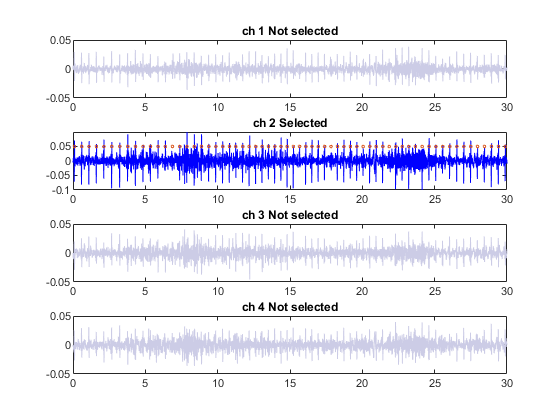

st = (max(ICs(ch,1:30000))/2)*ones(1,length(qrsF));
figure
for i = 1:4
    subplot(4,1,i)
    if i == ch
    plot(time, ICs(i,1:30000),'b')
    hold on 
    scatter(qrsF, st,4)
    tittlt = ['ch ', num2str(i),' Selected' ];
    title(tittlt)    
    else
    plot(time, ICs(i,1:30000),'Color',[0.8,0.8,0.9])
    tittlt = ['ch ', num2str(i),' Not selected' ];
    title(tittlt)
    end
end 

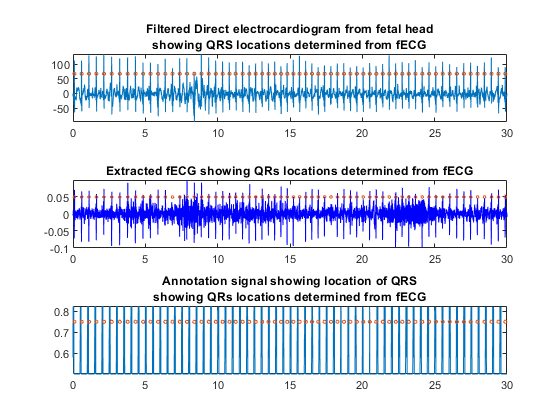


ss = (max(FiltECG(1,:))/2)*ones(1,length(qrsF));
san = 0.75*ones(1,length(qrsF));
st = (max(ICs(ch,1:30000))/2)*ones(1,length(qrsF));

figure
subplot(3,1,1)
plot(time,FiltECG(1,:))
hold on 
scatter(qrsF, ss,6)
hold off 
title(["Filtered Direct electrocardiogram from fetal head","showing QRS locations determined from fECG"])

subplot(3,1,2)
plot(time, ICs(ch,1:30000),'b')

hold on 
scatter(qrsF, st,4)
tittlt = ['Extracted fECG showing QRs locations determined from fECG' ];
title(tittlt)

subplot(3,1,3)    
plot(time,FiltECG(6,:))
hold on 
scatter(qrsF, san,6)
hold off 
title(["Annotation signal showing location of QRS" "showing QRs locations determined from fECG"])

heartRate = 60*(length(qrsF)/max(time+1/Fs))

heartRate = 128


disp(['estimated fetal heart rate is ' num2str(heartRate)])

estimated fetal heart rate is 128
